# Group Project Part 3: Least Squares

clear all;
clc;

## Initial Values


I0 = 10;
S0 = 990;
R0 = 0;
TestBeta = 0.3;
TestGamma = 0.1;
N = I0 + S0 + R0;
% Betai = .3; Gammai = .1;
% Betaii = 1; Gammaii = .1;
% Betaiii = 2; Gammaiii = .2;

k = ((TestBeta*S0)/N)-TestGamma;

Beta = [.3 1 2];
gamma = [.1 .1 .2];
ti = ["Seasonal Influenza","COVID","Measles"];
leg = ["Infected"];

h = 1;
t0 = 0; tf = 100;
tiledlayout(3,1);

## Part 1


for j = 1:length(Beta)
    Gamma=gamma(j);
    BN1=Beta(j)/1000;
    
    time = t0:h:tf;
    Rvals = zeros(size(time));
    Svals = zeros(size(time));
    Ivals = zeros(size(time));
    Nvals = zeros(size(time));
    
    Rvals(1) = R0;
    Svals(1) = S0;
    Ivals(1) = I0;
    Nvals(1) = 1000;
    dRdt = @(I) Gamma*I;                  
    dSdt = @(I,S) -BN1*S*I;
    dIdt = @(I,S) (BN1*S*I)-(Gamma*I);
        for i = 1:length(time)-1
            R=Rvals(i);
            S=Svals(i);
            I=Ivals(i);
            
            rk1 = dRdt(I);           % Runge Kutta Recovered K1 
            sk1 = dSdt(I,S);            % Runge Kutta Susceptible K1 
            ik1 = dIdt(I,S);           % Runge Kutta Infected K1
            
            ik2 = dIdt((I + ik1 * (h/2)) , S + sk1 * (h/2));           % Runge Kutta Infected K2
            rk2 = dRdt(I + ik1 * (h/2));           % Runge Kutta Recovered K2 
            sk2 = dSdt(I + ik1 * (h/2)  , (S + sk1 * (h/2)));           % Runge Kutta Susceptible K2
            
            sk3 = dSdt(I + ik2 * (h/2) ,(S + sk2 * (h/2)));            % Runge Kutta Susceptible K3 
            ik3 = dIdt((I + ik2 * (h/2)) ,S + sk2 * (h/2));           % Runge Kutta Infected K3
            rk3 = dRdt(I + ik2 * (h/2));           % Runge Kutta Recovered K3 
            
            ik4 = dIdt((I + ik3 * h),S + sk3 * h);           % Runge Kutta Infected K4
            sk4 = dSdt(I + ik3 * h , (S + sk3 * h));           % Runge Kutta Susceptible K4 
            rk4 = dRdt(I + ik3 * h);
            
            Rvals(i+1) = R + (1/6) * (rk1 + 2*(rk2) + 2*(rk3) + rk4) * h;
            Svals(i+1) = S + (1/6) * (sk1 + 2*(sk2) + 2*(sk3) + sk4) * h;
            Ivals(i+1) = I + (1/6) * (ik1 + 2*(ik2) + 2*(ik3) + ik4) * h;
            Nvals(i+1) = Rvals(i+1) + Svals(i+1) + Ivals(i+1);
        end
    data(j,1:101)= Ivals;    
end

disp(data)

   10.0000   12.1716   14.7988   17.9694   21.7848   26.3598   31.8225   38.3119   45.9741   54.9553   65.3919   77.3971   91.0425  106.3385  123.2119  141.4867  160.8708  180.9530  201.2159  221.0640  239.8666  257.0101  271.9500  284.2554  293.6385  299.9651  303.2483  303.6279  301.3417  296.6938  290.0250  281.6870  272.0232  261.3545  249.9707  238.1265  226.0399  213.8937  201.8376  189.9917  178.4497  167.2829  156.5435  146.2674  136.4776  127.1861  118.3963  110.1047  102.3027   94.9774   88.1130   81.6913   75.6931   70.0979   64.8849   60.0333   55.5224   51.3318   47.4419   43.8336   40.4887   37.3898   34.5202   31.8642   29.4069   27.1345   25.0337   23.0921   21.2984   19.6415   18.1116   16.6991   15.3953   14.1920   13.0818   12.0576   11.1128   10.2414    9.4378    8.6968    8.0136    7.3838    6.8031    6.2680    5.7747    5.3200    4.9011    4.5150    4.1592    3.8313    3.5293    3.2510    2.9945    2.7583    2.5407    2.3402    2.1555    1.9853    1.8286    1.6842

## Part 2

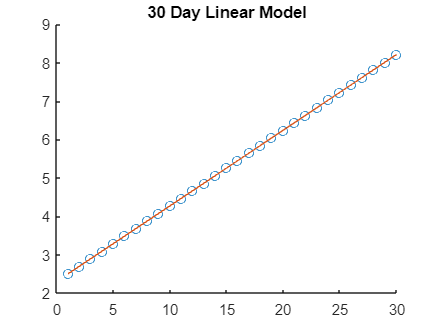

% Linear Model
lnIt = @(t) log(I0) +(k*t);
t30 = 1:30;
a130 = (30*sum(t30.*lnIt(t30))-(sum(t30)*sum(lnIt(t30))))/(30*sum(t30.^2)-sum(t30)^2);
a030 = ((1/30)*sum(lnIt(t30)))-(a130*(1/30)*sum(t30));
scatter(t30,lnIt(t30))
hold on
title('30 Day Linear Model')
plot(a130*t30+a030)
hold off


I0estLIN30 = a030

I0estLIN30 = 2.3026

BestLIN30 = (N*(a130 + Gamma(1)))/S0

BestLIN30 = 0.4010

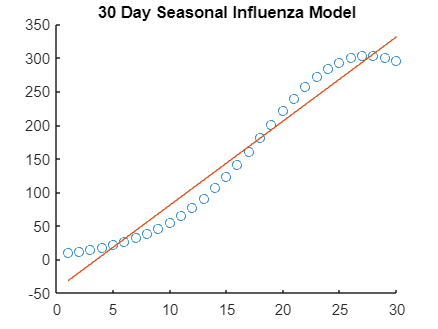


% Seasonal Influenza
a1SI30 = (30*sum(t30.*data(1,1:30))-(sum(t30)*sum(data(1,1:30))))/(30*sum(t30.^2)-sum(t30)^2);
a0SI30 = ((1/30)*sum(data(1,1:30)))-(a1SI30*(1/30)*sum(t30));
scatter(t30,data(1,1:30))
hold on
title('30 Day Seasonal Influenza Model')
plot(a1SI30*t30+a0SI30)
hold off


I0estSI30 = a0SI30

I0estSI30 = -44.3022

BestSI30 = (N*(a1SI30 + gamma(1)))/S0

BestSI30 = 12.7518

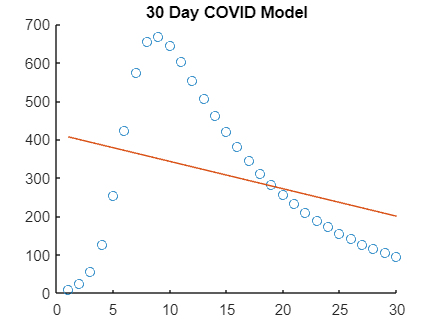


% COVID
a1C30 = (30*sum(t30.*data(2,1:30))-(sum(t30)*sum(data(2,1:30))))/(30*sum(t30.^2)-sum(t30)^2);
a0C30 = ((1/30)*sum(data(2,1:30)))-(a1C30*(1/30)*sum(t30));
scatter(t30,data(2,1:30))
hold on
title('30 Day COVID Model')
plot(a1C30*t30+a0C30)
hold off


I0estC30 = a0C30

I0estC30 = 414.0370

BestC30 = (N*(a1C30 + gamma(1)))/S0

BestC30 = -7.1046

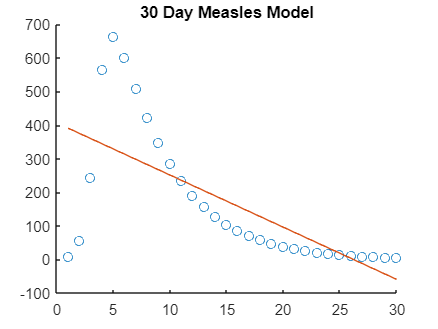


% Measles
a1M30 = (30*sum(t30.*data(3,1:30))-(sum(t30)*sum(data(3,1:30))))/(30*sum(t30.^2)-sum(t30)^2);
a0M30 = ((1/30)*sum(data(3,1:30)))-(a1M30*(1/30)*sum(t30));
scatter(t30,data(3,1:30))
hold on
title('30 Day Measles Model')
plot(a1M30*t30+a0M30)
hold off


I0estM30 = a0M30

I0estM30 = 406.3158

BestM30 = (N*(a1M30 + gamma(1)))/S0

BestM30 = -15.5805

## Part 3

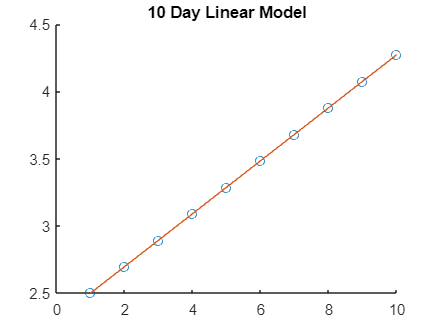

% Linear Model
lnIt = @(t) log(I0) +(k*t);
t10 = 1:10;
a110 = (10*sum(t10.*lnIt(t10))-(sum(t10)*sum(lnIt(t10))))/(10*sum(t10.^2)-sum(t10)^2);
a010 = ((1/10)*sum(lnIt(t10)))-(a110*(1/10)*sum(t10));
scatter(t10,lnIt(t10))
hold on
title('10 Day Linear Model')
plot(a110*t10+a010)
hold off


I0estLIN10 = a010

I0estLIN10 = 2.3026

BestLIN10 = (N*(a110 + gamma(1)))/S0

BestLIN10 = 0.3000

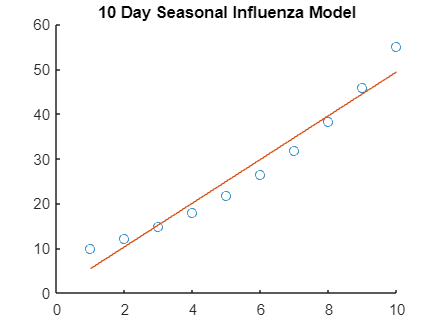


% Seasonal Influenza
a1SI10 = (10*sum(t10.*data(1,1:10))-(sum(t10)*sum(data(1,1:10))))/(10*sum(t10.^2)-sum(t10)^2);
a0SI10 = ((1/10)*sum(data(1,1:10)))-(a1SI10*(1/10)*sum(t10));
scatter(t10,data(1,1:10))
hold on
title('10 Day Seasonal Influenza Model')
plot(a1SI10*t10+a0SI10)
hold off


I0estSI10 = a0SI10

I0estSI10 = 0.5843

BestSI10 = (N*(a1SI10 + gamma(1)))/S0 

BestSI10 = 5.0286

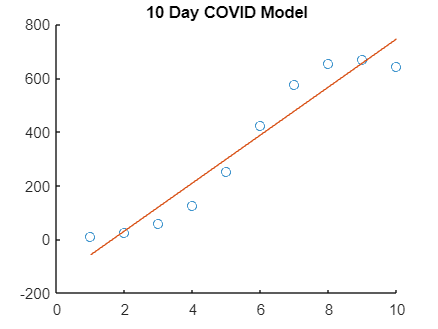


% COVID
a1C10 = (10*sum(t10.*data(2,1:10))-(sum(t10)*sum(data(2,1:10))))/(10*sum(t10.^2)-sum(t10)^2);
a0C10 = ((1/10)*sum(data(2,1:10)))-(a1C10*(1/10)*sum(t10));
scatter(t10,data(2,1:10))
hold on
title('10 Day COVID Model')
plot(a1C10*t10+a0C10)
hold off


I0estC10 = a0C10

I0estC10 = -147.2505

BestC10 = (N*(a1C10 + gamma(1)))/S0

BestC10 = 90.2940

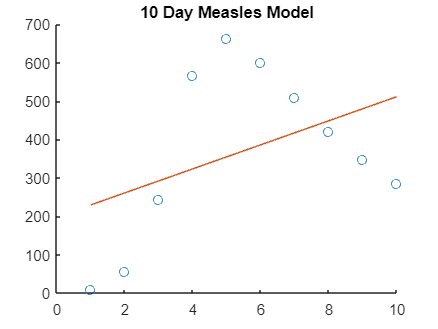


% Measles
a1M10 = (10*sum(t10.*data(3,1:10))-(sum(t10)*sum(data(3,1:10))))/(10*sum(t10.^2)-sum(t10)^2);
a0M10 = ((1/10)*sum(data(3,1:10)))-(a1M10*(1/10)*sum(t10));
scatter(t10,data(3,1:10))
hold on
title('10 Day Measles Model')
plot(a1M10*t10+a0M10)
hold off


I0estM10 = a0M10

I0estM10 = 198.0556

BestM10 = (N*(a1M10 + gamma(1)))/S0

BestM10 = 31.7346


% By decreasing the amount of values, the estimated I(0) improves to a
% greater accuracy to the actual value. This trend will continue because as
% the slope value of infected increases, the x-intercept of the graphs will
% decrease greater. This occurs because the least-squares regression is
% trying its best to match a non-linear model. If the model was reduced to
% even smaller value, for example half a day, the estimated I(0) would be
% signifcantly closer to 10. This a major downfall of the least squares
% regression method.

% Beta values displayed more of the key issues of running a linear least squares model on a non-linear
% model because it ultimately leads to poor approximations across the board with a lot of error. 
% Although a helpful tool to get an idea, the results can not be trusted as highly accurate when the 
% data doesn't follow some linear pattern.